## 1 system

% find equilibrium points
syms x [2,1]
S = solve(system1(x) == 0);
ep = [S.x1 S.x2]

$$ep = \left(\begin{array}{cc} 0 & 0\\ 1 & -1\\ -1 & 1 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system1(x), x)

$$jac = \left(\begin{array}{cc} 6\,{x_{1}}^{2}-1 & 1\\ -1 & -1 \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} -1 & 1\\ -1 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0-1.0\,\mathrm{i}\\ -1.0+1.0\,\mathrm{i} \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} 1 & -1 \end{array}\right)$$

$$\left(\begin{array}{cc} 5 & 1\\ -1 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -0.828\\ 4.828 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} -1 & 1 \end{array}\right)$$

$$\left(\begin{array}{cc} 5 & 1\\ -1 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -0.828\\ 4.828 \end{array}\right)$$

1 - устойчивый фокус

2 - седловая точка

3 - седловая точка

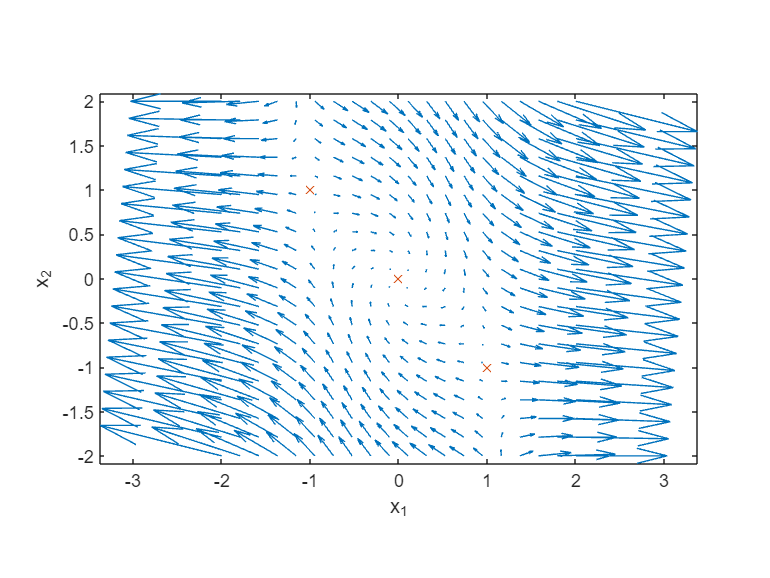

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 20), linspace(y_lim(1), y_lim(2), 20));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system1([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

Диаграмма векторного поля с выделенными точками равновесия системы

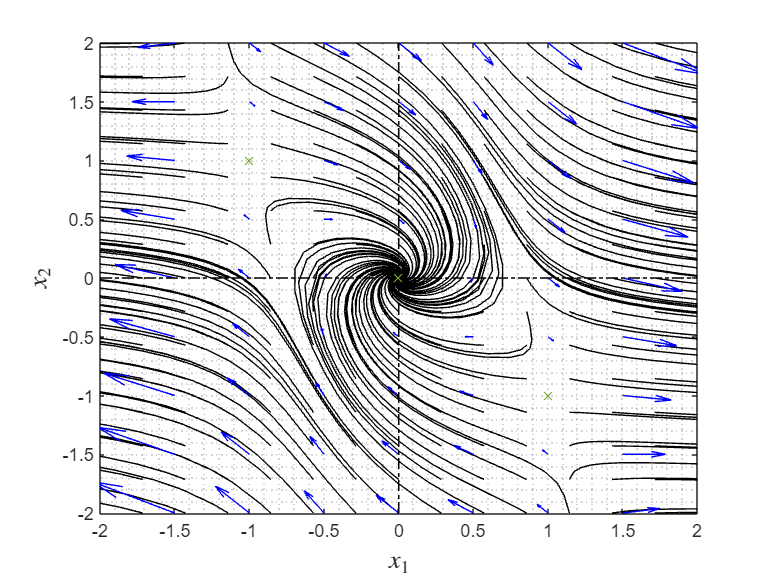

% phase portrait

tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 15), linspace(y_lim(1), y_lim(2), 15));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system1,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

## 2 system

% find equilibrium points
syms x [2,1]
S = solve(system2(x) == 0, 'Real', true);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0\\ 0 & 1.0\\ 1.0 & -1.0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system2(x), x)

$$jac = \left(\begin{array}{cc} x_{2}+1 & x_{1}\\ x_{2}-3\,{x_{1}}^{2} & x_{1}+2\,x_{2}-1 \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 1 & 0\\ 0 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cc} 2.0 & 0\\ 1.0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{c} 1.0\\ 2.0 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} 1.0 & -1.0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1.0\\ -4.0 & -2.0 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0+1.732\,\mathrm{i}\\ -1.0-1.732\,\mathrm{i} \end{array}\right)$$

1 - седловая точка

2 - неустойчивый узел

3 - устойчивый фокус

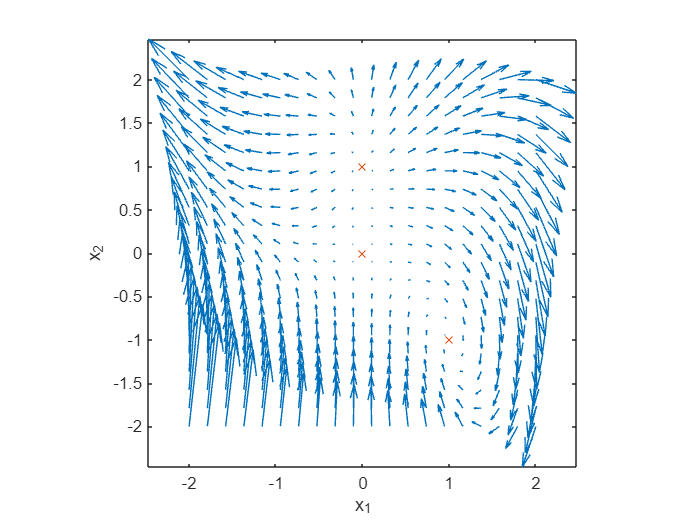

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 20), linspace(y_lim(1), y_lim(2), 20));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system2([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

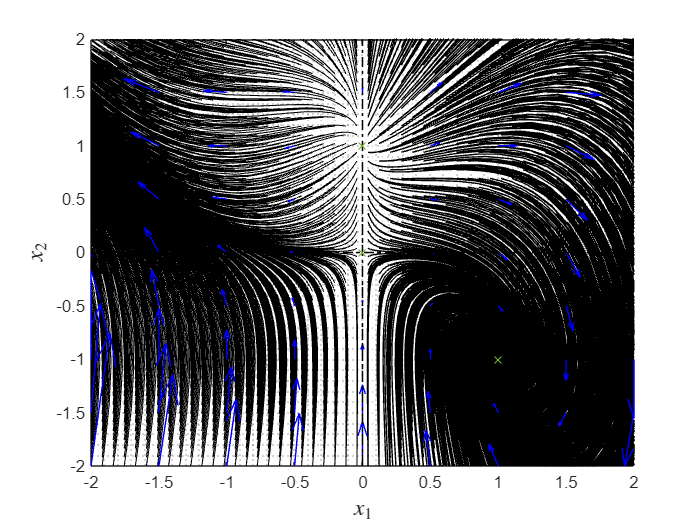

% phase portrait

tspan=[0,500];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 50), linspace(y_lim(1), y_lim(2), 50));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system2,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

## 3 system

xdot(1,1) = x(2);

xdot(2,1) = -x(1)+x(2)*(1-x(1)^2+0.1*x(1)^4);

    Данная система является нелинейным осциллятором. Значит в системе могут наблюдаться стационарные колебания, а следовательно соответствующая траектория будет являться замкнутой орбитой. Существование данной орбиты докажем ниже с помощью критерия Пуанкаре-Бендиксона.

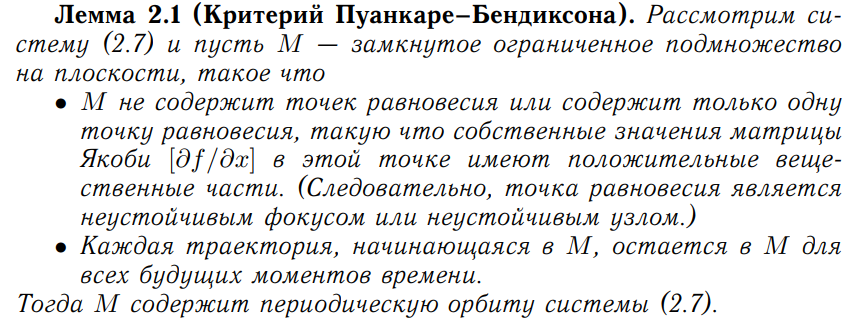

% find equilibrium points
syms x [2,1]
S = solve(system3(x) == 0, 'Real', true);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system3(x), x)

$$jac = \left(\begin{array}{cc} 0 & 1\\ -x_{2}\,\left(2\,x_{1}-\frac{2\,{x_{1}}^{3}}{5}\right)-1 & \frac{{x_{1}}^{4}}{10}-{x_{1}}^{2}+1 \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1\\ -1 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0.5-0.866\,\mathrm{i}\\ 0.5+0.866\,\mathrm{i} \end{array}\right)$$

1 - неустойчивый фокус

Докажем существование периодической орбиты в области вида M = {V(x)<=c}, где V(x) = x1^2+x2^2 и c = 5.

c = 5;
V = x1^2 + x2^2;

Траектории будут лежать внутри M, если f(x)*grad[V(x)] < 0  на границе V(x) = c.

Проверим это

f1 = x2;
f2 = -x1+x2*(1-x1^2+0.1*x1^4);
eqn = diff(V, x1)*f1 + diff(V, x2)*f2;
collect(eqn)

$$ans = \frac{{x_{2}}^{2}}{5}\,{x_{1}}^{4}+\left(-2\,{x_{2}}^{2}\right)\,{x_{1}}^{2}+2\,{x_{2}}^{2}$$

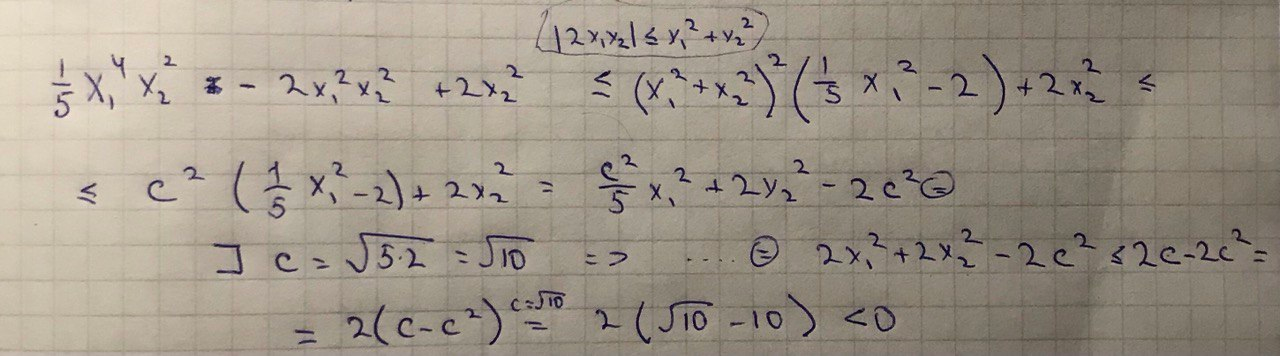

Условие критерия выполнено, следовательно внутри окружности радиуса sqrt(10) существует периодическая орбита.

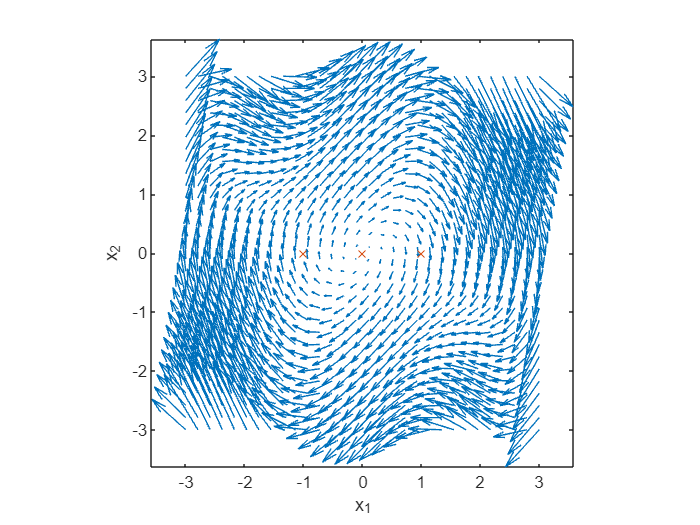

% phase plane
x_lim = [-3; 3];
y_lim = [-3; 3];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system3([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

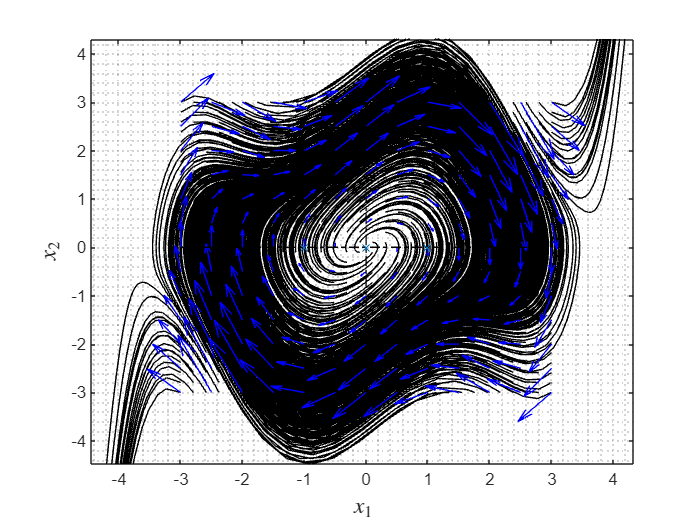

% phase portrait

tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system3,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

Наблюдаем периодическую орбиту. Также орбита является изолированной (доказательство для такого рода систем этого есть в книге Халила). Так как мы видим, что все траектории в окрестности орбиты стремятся к ней при t → ∞, то это устойчивый предельный цикл.

## 4 system

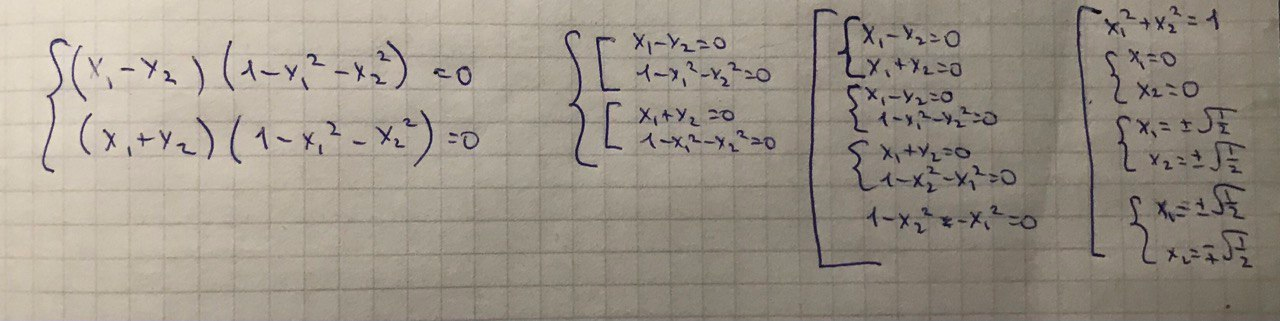

Имеем одну изолированную точку равновесия и континуум точек равновесия, расположенных на окружности радиуса 1.

% find equilibrium points
syms x [2,1]
syms t1 t2
S = solve(system4(x) == 0, x);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0\\ -1.0 & 0\\ 1.0 & 0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system4(x), x)

$$jac = \left(\begin{array}{cc} 1-{x_{1}}^{2}-{x_{2}}^{2}-2\,x_{1}\,\left(x_{1}-x_{2}\right) & {x_{1}}^{2}-2\,x_{2}\,\left(x_{1}-x_{2}\right)+{x_{2}}^{2}-1\\ 1-{x_{1}}^{2}-{x_{2}}^{2}-2\,x_{1}\,\left(x_{1}+x_{2}\right) & 1-{x_{1}}^{2}-{x_{2}}^{2}-2\,x_{2}\,\left(x_{1}+x_{2}\right) \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1\\ -1 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0.5-0.866\,\mathrm{i}\\ 0.5+0.866\,\mathrm{i} \end{array}\right)$$

1 (изолированная точка равновесия) - неустойчивый фокус

2 (континуум точек на окружности) - одно собственное значение = 0, значит подход линеаризации системы нельзя применить к данным точкам равновесия (точка не является гиперболической точкой равновесия). качественное поведение нелинейных уравнений состояния вблизи данной точки равновесия может существенно отличаться от качественного поведения линеаризованных уравнений состояния (либо седло, либо устойчивый узел)

Аналогичным образом, докажем что в области M = {c1<=V(x)<=c2}, где V(x) = x1^2+x2^2 и 0 < c1 < c2 существует периодическая орбита.

V = x1^2 + x2^2;
f1 = (x1-x2)*(1-x1^2-x2^2);
f2 = (x1+x2)*(1-x1^2-x2^2);
eqn = diff(V, x1)*f1 + diff(V, x2)*f2;
collect(eqn)

$$ans = -2\,{x_{1}}^{4}+\left(2-4\,{x_{2}}^{2}\right)\,{x_{1}}^{2}-2\,{x_{2}}^{2}\,\left({x_{2}}^{2}-1\right)$$

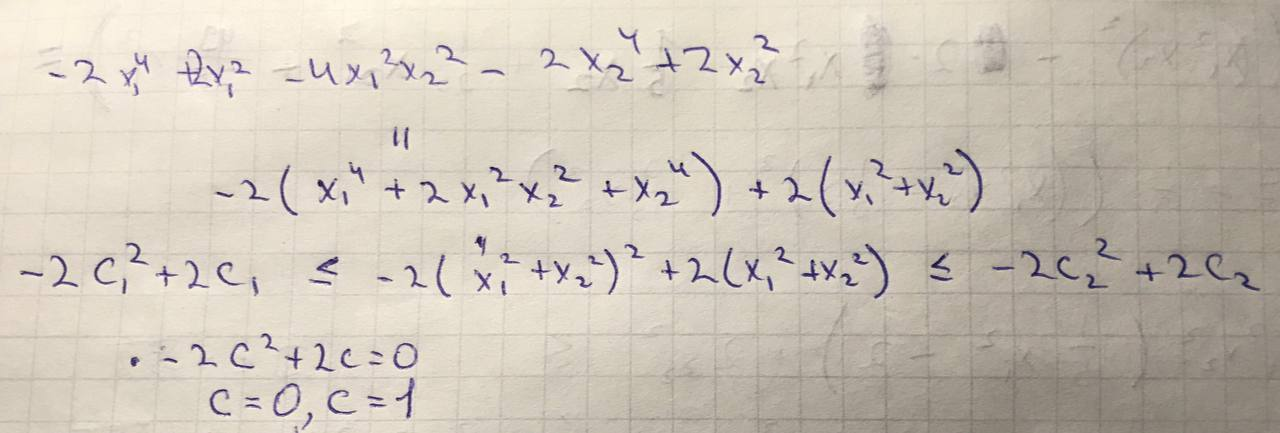

Так как мы может ограничить функцию 0 <= diff(V, x1)*f1 + diff(V, x2)*f2 <= 0 при c = 1 и при других 0 < c1 < c2 можем увидеть что траектории будут не выходить из кольца, то можем заключить что имеем устойчивый предельный цикл.

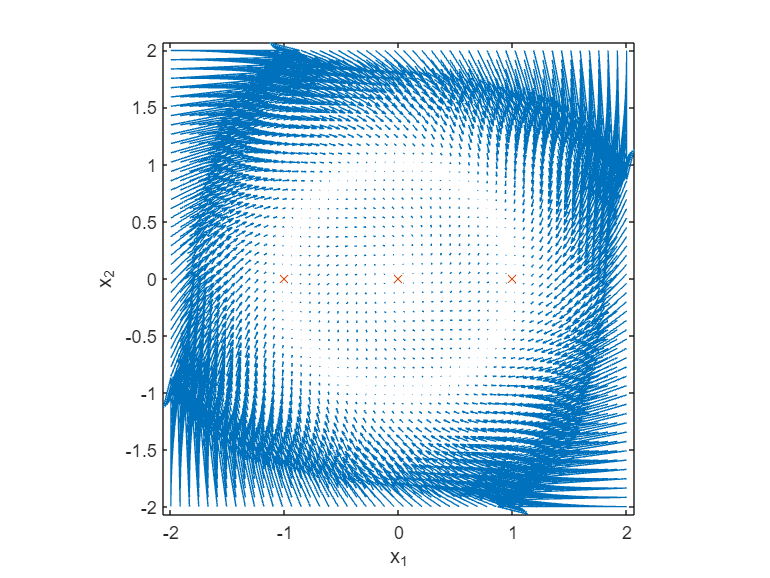

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 50), linspace(y_lim(1), y_lim(2), 50));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system4([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,10);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

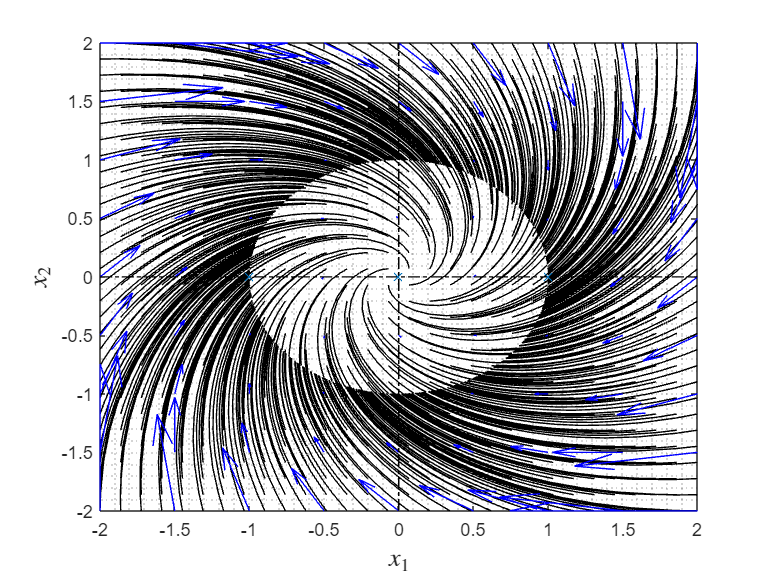

% phase portrait

tspan=[0,50];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system4,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

Наблюдаем устойчивый предельный цикл

## 5 system

% find equilibrium points
syms x [2,1]
S = solve(system5(x) == 0, 'Real', true);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0\\ -1.0 & -1.0\\ 1.0 & 1.0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system5(x), x)

$$jac = \left(\begin{array}{cc} -3\,{x_{1}}^{2} & 1\\ 1 & -3\,{x_{2}}^{2} \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} -1.0 & -1.0 \end{array}\right)$$

$$\left(\begin{array}{cc} -3.0 & 1\\ 1 & -3.0 \end{array}\right)$$

$$\left(\begin{array}{c} -2.0\\ -4.0 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} 1.0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cc} -3.0 & 1\\ 1 & -3.0 \end{array}\right)$$

$$\left(\begin{array}{c} -2.0\\ -4.0 \end{array}\right)$$

1 - седловая точка

2 - устойчивый узел

3 - устойчивый узел

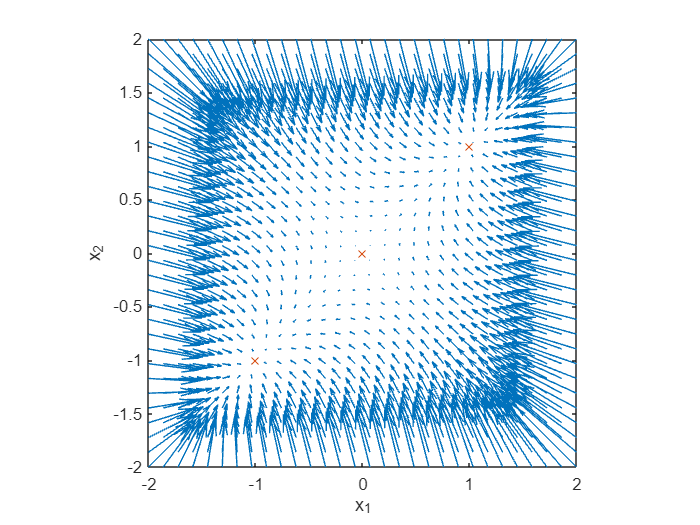

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system5([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

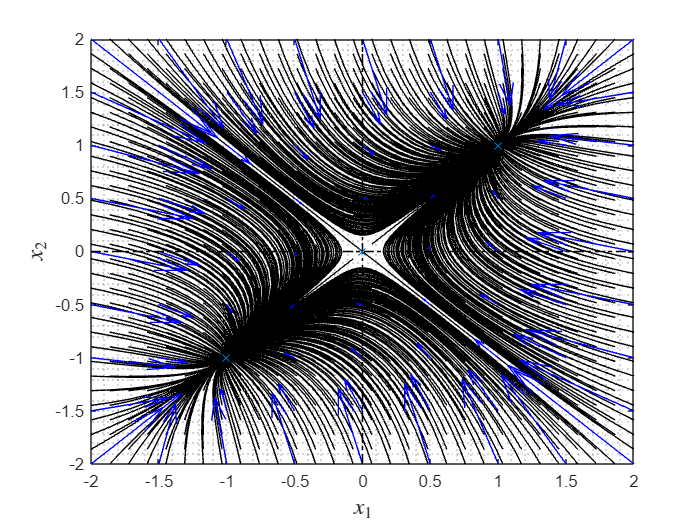

% phase portrait

tspan=[0,50];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system5,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off